load("DirtyValidNet.mat");

I = imread('../Semantic Segmentation Data/Testing data/45.jpg');
symbols = image2symbols(I, net, 20);

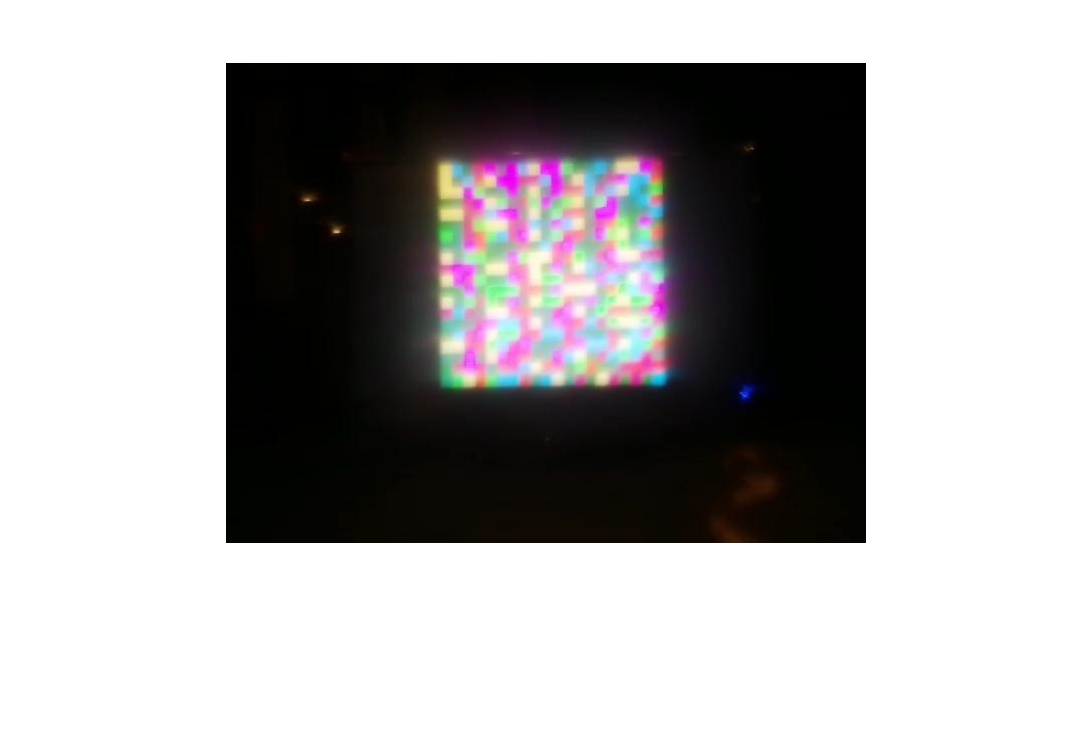

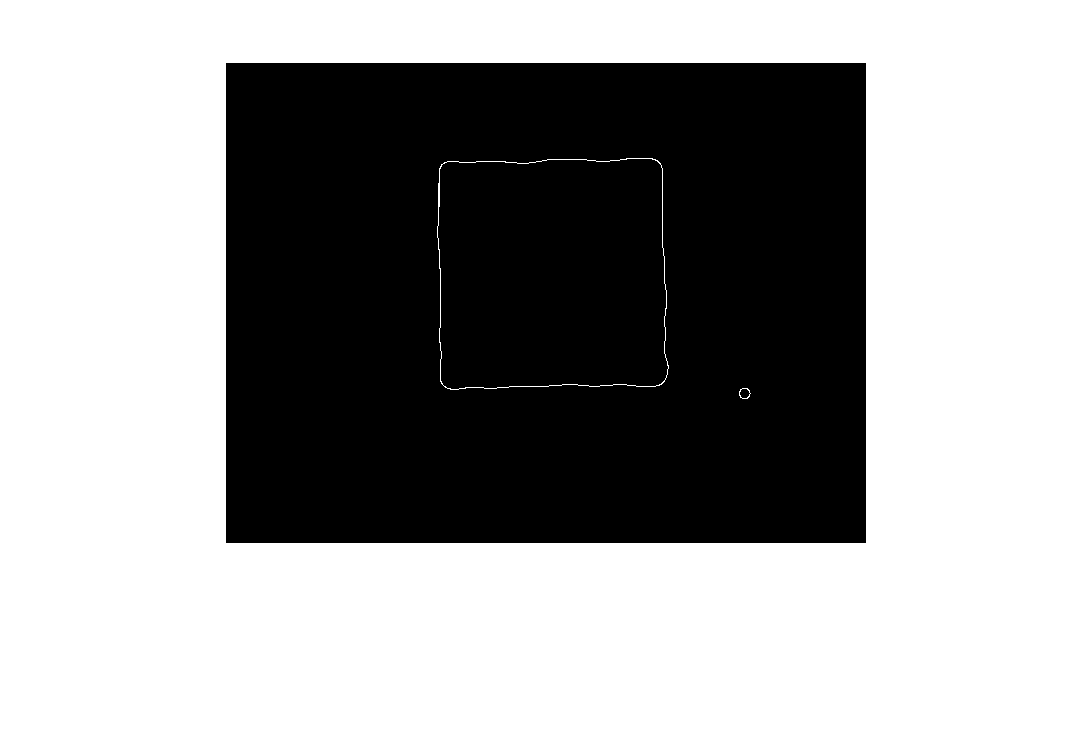

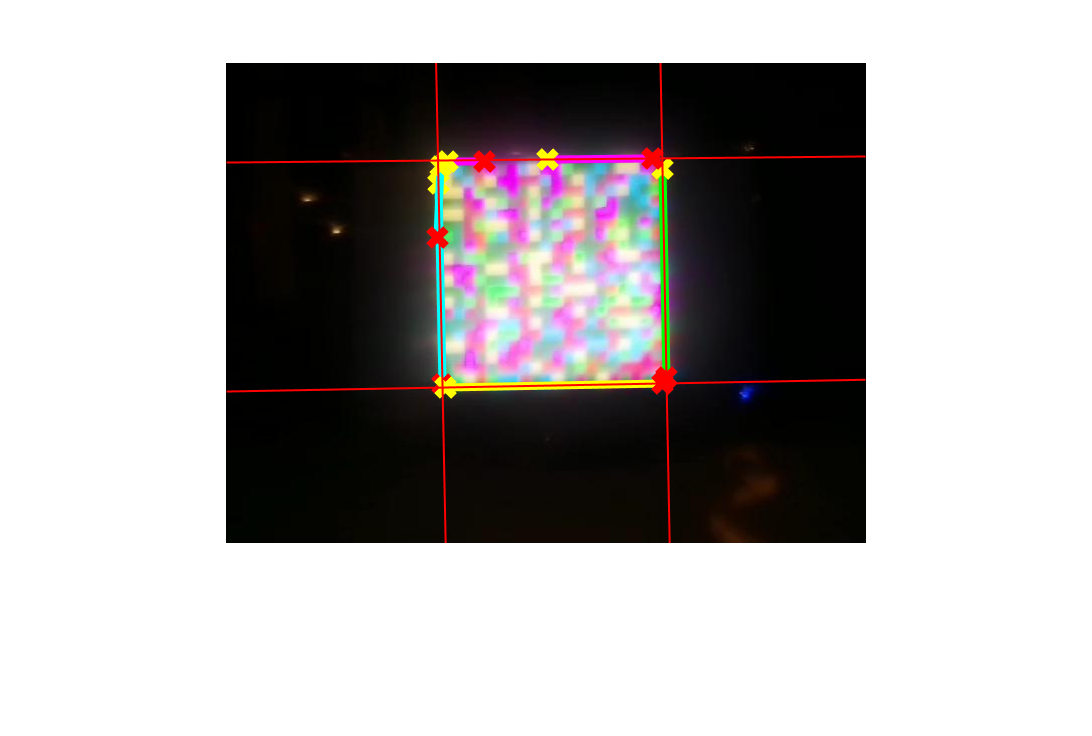

corners =   441.1134  320.9242
  436.8068   95.9066
  217.0608  325.0542
  212.5431   98.0424


img = imread('../Semantic Segmentation Data/Testing data/45.jpg');
figure;
imshow(img);
corners = weighting(net,img,1)

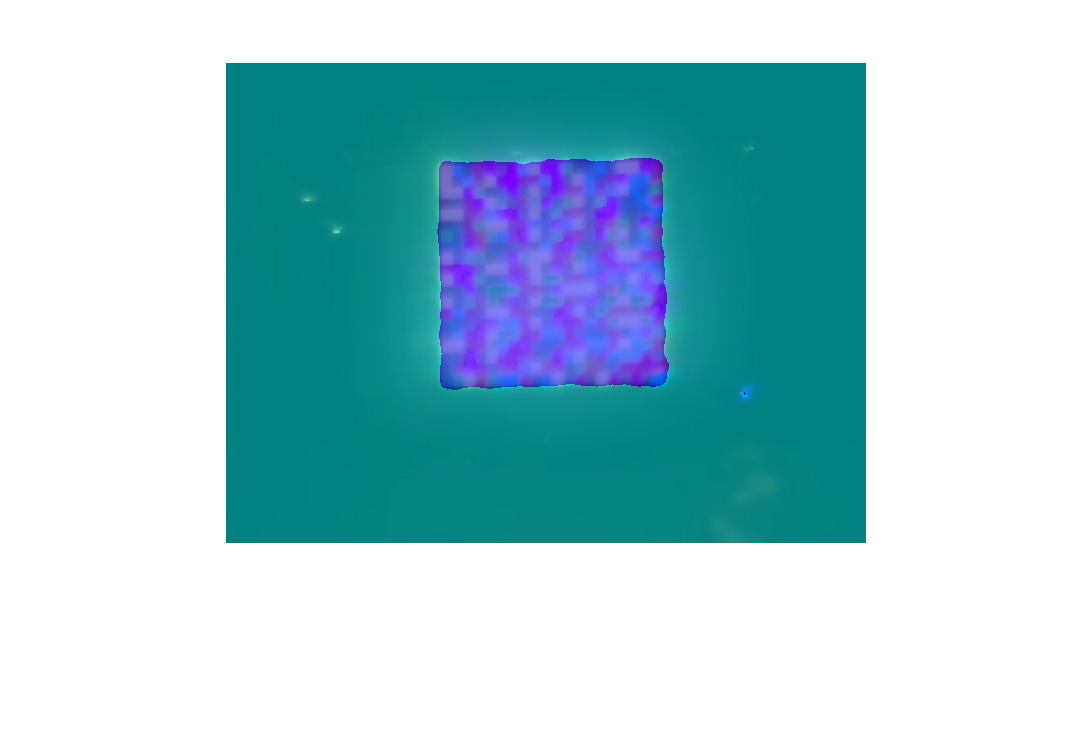

C=semanticseg(img,net);
B = labeloverlay(img,C);
figure;
imshow(B)

% Apply Perspective Warping followed by cropping of the frame
movingPoints = [corners(4,1) corners(4,2); corners(2,1),corners(2,2); corners(1,1),corners(1,2); corners(3,1),corners(3,2)];%coordinate of distorted corners

Unrecognized function or variable 'corners'.

fixedPoints=[0 0;size(img,1) 0;size(img,1) size(img,2);0 size(img,2)]; %coordinate of image's corners

tform = fitgeotrans(movingPoints,fixedPoints,'projective');
R=imref2d(size(img),[1 size(img,1)],[1 size(img,2)]);
frame=imwarp(img,tform,'OutputView',R);

figure;
imshow(frame);

% Apply grid for visual analysis (Remove for final code)
numSymbols = 20;
figure
imshow(frame);
axis on;
[rows, columns, numberOfColorChannels] = size(frame)
hold on;
for row = 1 : rows/numSymbols : rows
    line([1, columns], [row, row], 'Color', 'k');
end
for col = 1 : columns/numSymbols : columns
    line([col, col], [1, rows], 'Color', 'k');
end